Import linear distances

opts = delimitedTextImportOptions("NumVariables", 24);

% Specify range and delimiter
opts.DataLines = [2, 37];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Angle", "T1", "T2", "T3", "T4", "T5", "T6", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24"];
opts.SelectedVariableNames = ["Angle", "T1", "T2", "T3", "T4", "T5", "T6"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["T1", "T2", "T3", "T4", "T5", "T6"], "DecimalSeparator", ",");
opts = setvaropts(opts, ["T1", "T2", "T3", "T4", "T5", "T6"], "ThousandsSeparator", ".");

% Import the data
distance_per_degree_tab = readtable("C:\Daten\RU\Precision Machine Design\angle_calc\angle_over_rotations_full_system_conv_distance.csv", opts)

distance_per_degree_tab = 36×7 table
    Angle      T1         T2         T3         T4         T5         T6   
    _____    _______    _______    _______    _______    _______    _______

     10      0.70681    0.70681    0.70681    0.73626    0.70681    0.70681
      9      0.70681    0.73626    0.70681    0.73626    0.73626    0.73626
      8      0.73626    0.73626    0.73626    0.70681    0.70681    0.73626
      7      0.73626    0.70681    0.73626    0.70681    0.73626    0.73626
      6      0.73626    0.70681    0.73626    0.70681    0.73626    0.73626
      5      0.70681    0.76571    0.70681    0.76571    0.76571    0.70681
      4      0.76571    0.76571    0.76571    0.73626    0.73626    0.73626
      3      0.76571    0.70681    0.765

distances = table2array(distance_per_degree_tab(:,2:end))

distances =     0.7068    0.7068    0.7068    0.7363    0.7068    0.7068
    0.7068    0.7363    0.7068    0.7363    0.7363    0.7363
    0.7363    0.7363    0.7363    0.7068    0.7068    0.7363
    0.7363    0.7068    0.7363    0.7068    0.7363    0.7363
    0.7363    0.7068    0.7363    0.7068    0.7363    0.7363
    0.7068    0.7657    0.7068    0.7657    0.7657    0.7068
    0.7657    0.7657    0.7657    0.7363    0.7363    0.7363
    0.7657    0.7068    0.7657    0.7068    0.7068    0.7068
    0.7068    0.7657    0.7068    0.7363    0.7363    0.7363
    0.9424    0.7657    0.7952    0.7657    0.7657    0.7657


clear opts


opts = delimitedTextImportOptions("NumVariables", 24);

% Specify range and delimiter
opts.DataLines = [5, 40];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "Var23", "Var24"];
opts.SelectedVariableNames = ["VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "double", "double", "double", "double", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var23", "Var24"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var23", "Var24"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22"], "DecimalSeparator", ",");
opts = setvaropts(opts, ["VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22"], "ThousandsSeparator", ".");

% Import the data
angleoverrotationsfullsystemconvdistance = readtable("C:\Daten\RU\Precision Machine Design\angle_calc\angle_over_rotations_full_system_conv_distance.csv", opts);
rotations_per_angle = table2array(angleoverrotationsfullsystemconvdistance)

rotations_per_angle =    10.0000   12.0000   12.0000   12.0000   12.5000   12.0000   12.0000
    9.0000   12.0000   12.5000   12.0000   12.5000   12.5000   12.5000
    8.0000   12.5000   12.5000   12.5000   12.0000   12.0000   12.5000
    7.0000   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
    6.0000   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
    5.0000   12.0000   13.0000   12.0000   13.0000   13.0000   12.0000
    4.0000   13.0000   13.0000   13.0000   12.5000   12.5000   12.5000
    3.0000   13.0000   12.0000   13.0000   12.0000   12.0000   12.0000
    2.0000   12.0000   13.0000   12.0000   12.5000   12.5000   12.5000
    1.0000   16.0000   13.0000   13.5000   13.0000   13.0000   13.0000


clear opts

angle_count = rotations_per_angle(:,1)

angle_count =     10
     9
     8
     7
     6
     5
     4
     3
     2
     1


rotations = rotations_per_angle(:,2:end)

rotations =    12.0000   12.0000   12.0000   12.5000   12.0000   12.0000
   12.0000   12.5000   12.0000   12.5000   12.5000   12.5000
   12.5000   12.5000   12.5000   12.0000   12.0000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.0000   13.0000   12.0000   13.0000   13.0000   12.0000
   13.0000   13.0000   13.0000   12.5000   12.5000   12.5000
   13.0000   12.0000   13.0000   12.0000   12.0000   12.0000
   12.0000   13.0000   12.0000   12.5000   12.5000   12.5000
   16.0000   13.0000   13.5000   13.0000   13.0000   13.0000


starting_point = 113.77

starting_point = 113.7700


clear total_distance

cumsum(distances(:,1))

ans =     0.7068
    1.4136
    2.1499
    2.8862
    3.6224
    4.3292
    5.0949
    5.8607
    6.5675
    7.5099



for k = 1:size(distances, 2)

total_distance(:,k) = cumsum(distances(:,k))

end

total_distance =     0.7068
    1.4136
    2.1499
    2.8862
    3.6224
    4.3292
    5.0949
    5.8607
    6.5675
    7.5099


total_distance =     0.7068    0.7068
    1.4136    1.4431
    2.1499    2.1793
    2.8862    2.8862
    3.6224    3.5930
    4.3292    4.3587
    5.0949    5.1244
    5.8607    5.8312
    6.5675    6.5969
    7.5099    7.3626


total_distance =     0.7068    0.7068    0.7068
    1.4136    1.4431    1.4136
    2.1499    2.1793    2.1499
    2.8862    2.8862    2.8862
    3.6224    3.5930    3.6224
    4.3292    4.3587    4.3292
    5.0949    5.1244    5.0949
    5.8607    5.8312    5.8607
    6.5675    6.5969    6.5675
    7.5099    7.3626    7.3626


total_distance =     0.7068    0.7068    0.7068    0.7363
    1.4136    1.4431    1.4136    1.4725
    2.1499    2.1793    2.1499    2.1793
    2.8862    2.8862    2.8862    2.8862
    3.6224    3.5930    3.6224    3.5930
    4.3292    4.3587    4.3292    4.3587
    5.0949    5.1244    5.0949    5.0949
    5.8607    5.8312    5.8607    5.8018
    6.5675    6.5969    6.5675    6.5380
    7.5099    7.3626    7.3626    7.3037


total_distance =     0.7068    0.7068    0.7068    0.7363    0.7068
    1.4136    1.4431    1.4136    1.4725    1.4431
    2.1499    2.1793    2.1499    2.1793    2.1499
    2.8862    2.8862    2.8862    2.8862    2.8862
    3.6224    3.5930    3.6224    3.5930    3.6224
    4.3292    4.3587    4.3292    4.3587    4.3881
    5.0949    5.1244    5.0949    5.0949    5.1244
    5.8607    5.8312    5.8607    5.8018    5.8312
    6.5675    6.5969    6.5675    6.5380    6.5675
    7.5099    7.3626    7.3626    7.3037    7.3332


total_distance =     0.7068    0.7068    0.7068    0.7363    0.7068    0.7068
    1.4136    1.4431    1.4136    1.4725    1.4431    1.4431
    2.1499    2.1793    2.1499    2.1793    2.1499    2.1793
    2.8862    2.8862    2.8862    2.8862    2.8862    2.9156
    3.6224    3.5930    3.6224    3.5930    3.6224    3.6519
    4.3292    4.3587    4.3292    4.3587    4.3881    4.3587
    5.0949    5.1244    5.0949    5.0949    5.1244    5.0949
    5.8607    5.8312    5.8607    5.8018    5.8312    5.8018
    6.5675    6.5969    6.5675    6.5380    6.5675    6.5380
    7.5099    7.3626    7.3626    7.3037    7.3332    7.3037



total_distance(11,:) = []

total_distance =     0.7068    0.7068    0.7068    0.7363    0.7068    0.7068
    1.4136    1.4431    1.4136    1.4725    1.4431    1.4431
    2.1499    2.1793    2.1499    2.1793    2.1499    2.1793
    2.8862    2.8862    2.8862    2.8862    2.8862    2.9156
    3.6224    3.5930    3.6224    3.5930    3.6224    3.6519
    4.3292    4.3587    4.3292    4.3587    4.3881    4.3587
    5.0949    5.1244    5.0949    5.0949    5.1244    5.0949
    5.8607    5.8312    5.8607    5.8018    5.8312    5.8018
    6.5675    6.5969    6.5675    6.5380    6.5675    6.5380
    7.5099    7.3626    7.3626    7.3037    7.3332    7.3037


angle_count(11) = []

angle_count =     10
     9
     8
     7
     6
     5
     4
     3
     2
     1



distance_offset = total_distance+(starting_point-total_distance(10,:))

distance_offset =   106.9669  107.1142  107.1142  107.2025  107.1436  107.1731
  107.6737  107.8504  107.8210  107.9388  107.8799  107.9093
  108.4100  108.5867  108.5573  108.6456  108.5867  108.6456
  109.1463  109.2935  109.2935  109.3524  109.3230  109.3819
  109.8825  110.0003  110.0298  110.0592  110.0592  110.1181
  110.5893  110.7660  110.7366  110.8249  110.8249  110.8249
  111.3551  111.5318  111.5023  111.5612  111.5612  111.5612
  112.1208  112.2386  112.2680  112.2680  112.2680  112.2680
  112.8276  113.0043  112.9748  113.0043  113.0043  113.0043
  113.7700  113.7700  113.7700  113.7700  113.7700  113.7700


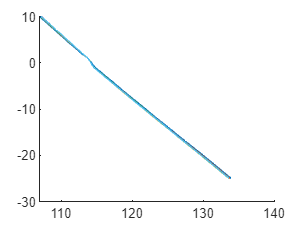


figure()
for i = 1:size(distance_offset,2)
    hold on
    plot(distance_offset(:,i), angle_count)
end

rotations(isnan(rotations)) = 0

rotations =    12.0000   12.0000   12.0000   12.5000   12.0000   12.0000
   12.0000   12.5000   12.0000   12.5000   12.5000   12.5000
   12.5000   12.5000   12.5000   12.0000   12.0000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.0000   13.0000   12.0000   13.0000   13.0000   12.0000
   13.0000   13.0000   13.0000   12.5000   12.5000   12.5000
   13.0000   12.0000   13.0000   12.0000   12.0000   12.0000
   12.0000   13.0000   12.0000   12.5000   12.5000   12.5000
   16.0000   13.0000   13.5000   13.0000   13.0000   13.0000



cumsum(rotations(:,1))

ans =    12.0000
   24.0000
   36.5000
   49.0000
   61.5000
   73.5000
   86.5000
   99.5000
  111.5000
  127.5000



clear total_rot

for k = 1:size(rotations, 2)

total_rot(:,k) = cumsum(rotations(:,k));

end


total_rot(10,:) = []

total_rot =    12.0000   12.0000   12.0000   12.5000   12.0000   12.0000
   24.0000   24.5000   24.0000   25.0000   24.5000   24.5000
   36.5000   37.0000   36.5000   37.0000   36.5000   37.0000
   49.0000   49.0000   49.0000   49.0000   49.0000   49.5000
   61.5000   61.0000   61.5000   61.0000   61.5000   62.0000
   73.5000   74.0000   73.5000   74.0000   74.5000   74.0000
   86.5000   87.0000   86.5000   86.5000   87.0000   86.5000
   99.5000   99.0000   99.5000   98.5000   99.0000   98.5000
  111.5000  112.0000  111.5000  111.0000  111.5000  111.0000
  127.5000  125.0000  125.0000  124.0000  124.5000  124.0000



total_rotation = total_rot

total_rotation =    12.0000   12.0000   12.0000   12.5000   12.0000   12.0000
   24.0000   24.5000   24.0000   25.0000   24.5000   24.5000
   36.5000   37.0000   36.5000   37.0000   36.5000   37.0000
   49.0000   49.0000   49.0000   49.0000   49.0000   49.5000
   61.5000   61.0000   61.5000   61.0000   61.5000   62.0000
   73.5000   74.0000   73.5000   74.0000   74.5000   74.0000
   86.5000   87.0000   86.5000   86.5000   87.0000   86.5000
   99.5000   99.0000   99.5000   98.5000   99.0000   98.5000
  111.5000  112.0000  111.5000  111.0000  111.5000  111.0000
  127.5000  125.0000  125.0000  124.0000  124.5000  124.0000




rotation_offset = total_rotation-total_rotation(11,:)

rotation_offset =  -132.5000 -127.0000 -127.0000 -125.0000 -126.5000 -125.5000
 -120.5000 -114.5000 -115.0000 -112.5000 -114.0000 -113.0000
 -108.0000 -102.0000 -102.5000 -100.5000 -102.0000 -100.5000
  -95.5000  -90.0000  -90.0000  -88.5000  -89.5000  -88.0000
  -83.0000  -78.0000  -77.5000  -76.5000  -77.0000  -75.5000
  -71.0000  -65.0000  -65.5000  -63.5000  -64.0000  -63.5000
  -58.0000  -52.0000  -52.5000  -51.0000  -51.5000  -51.0000
  -45.0000  -40.0000  -39.5000  -39.0000  -39.5000  -39.0000
  -33.0000  -27.0000  -27.5000  -26.5000  -27.0000  -26.5000
  -17.0000  -14.0000  -14.0000  -13.5000  -14.0000  -13.5000


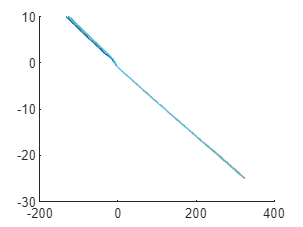


figure()
for i = 1:size(rotation_offset,2)
    hold on
    plot(rotation_offset(:,i), angle_count)
end

Calculate system range 

rotation_calc = rotations

rotation_calc =    12.0000   12.0000   12.0000   12.5000   12.0000   12.0000
   12.0000   12.5000   12.0000   12.5000   12.5000   12.5000
   12.5000   12.5000   12.5000   12.0000   12.0000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.0000   13.0000   12.0000   13.0000   13.0000   12.0000
   13.0000   13.0000   13.0000   12.5000   12.5000   12.5000
   13.0000   12.0000   13.0000   12.0000   12.0000   12.0000
   12.0000   13.0000   12.0000   12.5000   12.5000   12.5000
   16.0000   13.0000   13.5000   13.0000   13.0000   13.0000



rotation_calc(11,:) = []

rotation_calc =    12.0000   12.0000   12.0000   12.5000   12.0000   12.0000
   12.0000   12.5000   12.0000   12.5000   12.5000   12.5000
   12.5000   12.5000   12.5000   12.0000   12.0000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.5000   12.0000   12.5000   12.0000   12.5000   12.5000
   12.0000   13.0000   12.0000   13.0000   13.0000   12.0000
   13.0000   13.0000   13.0000   12.5000   12.5000   12.5000
   13.0000   12.0000   13.0000   12.0000   12.0000   12.0000
   12.0000   13.0000   12.0000   12.5000   12.5000   12.5000
   16.0000   13.0000   13.5000   13.0000   13.0000   13.0000



trials_rot = mean(rotation_calc)

trials_rot =    13.4286   13.2714   13.2429   13.2000   13.2000   13.2000


mean_rot = mean(trials_rot)

mean_rot = 13.2571

sd_rot = std(trials_rot)

sd_rot = 0.0890


sys_range = 1/mean_rot

sys_range = 0.0754

goal_range = 1

goal_range = 1


prob_angle = sys_range/goal_range

prob_angle = 0.0754


rot_target = mean_rot

rot_target = 13.2571

% Step 1: Calculate Expected Angles Using Mean Rotations per Degree
rotations_per_degree = mean_rot;  % Average rotations per degree
expected_angles = linspace(-10,25,100);  % Linear model

angle_count = rotations_per_angle(:,1)

angle_count =     10
     9
     8
     7
     6
     5
     4
     3
     2
     1



mean_offset = mean_rot*-angle_count

mean_offset =  -132.5714
 -119.3143
 -106.0571
  -92.8000
  -79.5429
  -66.2857
  -53.0286
  -39.7714
  -26.5143
  -13.2571



% Step 2: Plot Experimental Data and Linear Model
angle = figure('Position', [0 0 1200 800]);
hold on;
for i = 1:size(rotation_offset,2)
    plot(angle_count(1:35),rotation_offset(:,i),"xk","MarkerSize",10);  % Experimental data
end
plot(angle_count+0.5,mean_offset,  "r--", "LineWidth",2)
plot(angle_count-0.5,mean_offset,  "r--", "LineWidth",2)
xlabel('Angle (degrees)');
ylabel('Rotations');
title('Experimental Data vs. Linear Model');
legend('Experimental Data', '', '', '', '', '', "Linear Model Boundaries");

% Step 3: Calculate Deviations and Count Points within ±0.5° Tolerance
deviation = abs(abs(rotation_offset)-abs(mean_offset(1:35)));  % Absolute deviation from model
within_tolerance = deviation <= 0.5*mean_rot;  % Logical array for points within tolerance

ylim([-150 350])
xlim([-27 11])
% Count number of points within tolerance
num_within_tolerance = sum(sum(within_tolerance))

num_within_tolerance = 198

total_points = size(deviation,2)*size(deviation,1)

total_points = 210

percentage_within_tolerance = (num_within_tolerance / total_points) * 100

percentage_within_tolerance = 94.2857


% Display results
fprintf('Number of points within ±0.5° tolerance: %d out of %d (%.2f%%)\n', ...
        num_within_tolerance, total_points, percentage_within_tolerance);

Number of points within ±0.5° tolerance: 198 out of 210 (94.29%)


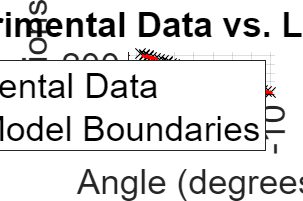

xticklabels(["" "20" "" "10" "" "0" "" "-10"])
fontsize(angle, 24, "points");
grid("on")

save_path_energy = 'C:\Daten\RU\Precision Machine Design\angle_calc\fig_fr1.eps';
saveas(gcf, save_path_energy);

Information content for FR1

angle_count_no0 = [angle_count(1:10); angle_count(12:end)]

angle_count_no0 =     10
     9
     8
     7
     6
     5
     4
     3
     2
     1


tolerance_min = -mean_rot*angle_count_no0-(mean_rot/2)

tolerance_min =  -139.2000
 -125.9429
 -112.6857
  -99.4286
  -86.1714
  -72.9143
  -59.6571
  -46.4000
  -33.1429
  -19.8857


tolerance_max = -mean_rot*angle_count_no0(1:35)+(mean_rot/2)

tolerance_max =  -125.9429
 -112.6857
  -99.4286
  -86.1714
  -72.9143
  -59.6571
  -46.4000
  -33.1429
  -19.8857
   -6.6286


std_dev_inf = std(rotation_offset,[],2)

std_dev_inf =     2.6972
    2.8882
    2.7824
    2.6972
    2.6347
    2.8534
    2.6771
    2.3166
    2.5183
    1.3292


mean_inf = mean(rotation_offset,2) 

mean_inf =  -127.2500
 -114.9167
 -102.5833
  -90.2500
  -77.9167
  -65.4167
  -52.6667
  -40.3333
  -27.9167
  -14.3333


std_error = std_dev_inf/sqrt(length(mean_rot))

std_error =     2.6972
    2.8882
    2.7824
    2.6972
    2.6347
    2.8534
    2.6771
    2.3166
    2.5183
    1.3292


tol_min_z = abs(mean_inf-tolerance_min)./std_dev_inf

tol_min_z =     4.4305
    3.8177
    3.6308
    3.4030
    3.1331
    2.6276
    2.6112
    2.6188
    2.0753
    4.1774


tol_max_z = abs(mean_inf-tolerance_max)./std_dev_inf

tol_max_z =     0.4846
    0.7724
    1.1338
    1.5121
    1.8986
    2.0185
    2.3409
    3.1039
    3.1891
    5.7967


% tol_min_prob = 1-(min(normcdf(tol_min_z, 0, 1), 1 - normcdf(tol_min_z, 0, 1)))
% tol_max_prob = 1-(min(normcdf(tol_max_z, 0, 1), 1 - normcdf(tol_max_z, 0, 1)))
tol_min_prob = 1-normcdf(tol_min_z, 0, 1)

tol_min_prob =     0.0000
    0.0001
    0.0001
    0.0003
    0.0009
    0.0043
    0.0045
    0.0044
    0.0190
    0.0000


tol_max_prob = 1-normcdf(tol_max_z, 0, 1)

tol_max_prob =     0.3140
    0.2199
    0.1284
    0.0652
    0.0288
    0.0218
    0.0096
    0.0010
    0.0007
    0.0000


prob_success_FR1 = mean(1-(tol_min_prob+tol_max_prob))

prob_success_FR1 = 0.9301



% tol_min_prob = (2 * min(normcdf(tol_min_z, 0, 1), 1 - normcdf(tol_min_z, 0, 1)))
% tol_max_prob = (2 * min(normcdf(tol_max_z, 0, 1), 1 - normcdf(tol_max_z, 0, 1)))
% prob_success_FR1 = (tol_min_prob+tol_max_prob)

Information content

% Define the dependency matrix (1 represents dependencies, 0 otherwise)
dependency_matrix = [
    1, 0, 0;  % FR1 depends only on DP1
    1, 1, 0;  % FR2 depends on both DP1 and DP2
    0, 0, 1   % FR3 depends only on DP3
];

% Set independent probabilities of meeting each FR
% (In a real case, these would be derived from system tolerances and specifications)
P_FR1 = prob_success_FR1;  % Probability of meeting FR1 requirements
P_FR2 = 0.9583;  % Probability of meeting FR2 requirements
P_FR3 = 1;  % Probability of meeting FR3 requirements

% Define conditional probability for FR2 given FR1 due to dependency
P_FR2_given_FR1 = 0.9583%*prob_success_FR1;  % Probability of meeting FR2 given FR1 is met

P_FR2_given_FR1 = 0.9583


% Calculate joint probabilities based on dependencies
P_FR1_and_FR2 = P_FR1 * P_FR2_given_FR1;  % Joint probability for coupled FR1 and FR2
P_FR3_independent = P_FR3;                % FR3 is independent in this case

% Total system probability (joint probability of all FRs being met)
P_system = P_FR1_and_FR2 * P_FR3_independent

P_system = 0.8914


% Calculate information content for each FR and total system
I_FR1 = -log2(P_FR1);
I_FR2 = -log2(P_FR2_given_FR1);
I_FR3 = -log2(P_FR3);
I_total = -log2(P_system);

% Display the results
fprintf('Information Content for FR1: %.4f bits\n', I_FR1);

Information Content for FR1: 0.1045 bits


fprintf('Information Content for FR2 (conditional): %.4f bits\n', I_FR2);

Information Content for FR2 (conditional): 0.0615 bits


fprintf('Information Content for FR3: %.4f bits\n', I_FR3);

Information Content for FR3: -0.0000 bits


fprintf('Total Information Content for the system: %.4f bits\n', I_total);

Total Information Content for the system: 0.1659 bits
